# Projeto 

## META 1

## 1

% Criar tabela
path = "data/36"

path = "data/36"

files = dir(path)

files = 502×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


filteredFiles = files([files.isdir] == 0);
tab = struct2table(filteredFiles)

tab = 500×6 table
         name                                      folder                                           date              bytes    isdir     datenum  
    _______________    _______________________________________________________________    ________________________    _____    _____    __________

    {'0_36_0.wav' }    {'/Users/franciscosantos/Documents/GitHub/Projeto_ATD/data/36'}    {'28-Dez-2020 07:38:02'}    77318    false    7.3815e+05
    {'0_36_1.wav' }    {'/Users/franciscosantos/Documents/GitHub/Projeto_ATD/data/36'}    {'28-Dez-2020 07:38:02'}    72478    false    7.3815e+05
    {'0_36_10.wav'}    {'/Users/franciscosantos/Documents/GitHub/Projeto_ATD/data/36'}    {'28-Dez-2020 07:38:02'}    87908    false    7.3815e+05
    {'0_36_11.wav'}    {'/Users/franciscos

% Número de arquivos
nFiles = height(tab);

digits = zeros(nFiles, 1);
participants = zeros(nFiles, 1);
repetitions = zeros(nFiles, 1);

for i = 1:nFiles
    filename = tab.name{i};
    % Remover a extensão (ex.: '.wav')
    [~, nameNoExt, ~] = fileparts(filename);
    % Separar os componentes usando o underline como delimitador
    parts = split(nameNoExt, '_');
    
    if numel(parts) >= 3
        % Converter os componentes para número
        digits(i) = str2double(parts{1});
        participants(i) = str2double(parts{2});
        repetitions(i) = str2double(parts{3});
    else
        warning('Formato de nome inesperado: %s', filename);
        digits(i) = NaN;
        participants(i) = NaN;
        repetitions(i) = NaN;
    end
end

% Criar a nova tabela
newTable = table(tab.folder, tab.name, participants, digits, repetitions, ...
    'VariableNames', {'AudioDirectory', 'FileName', 'Participant', 'Digit', 'Repetitions'})

newTable = 500×5 table
                            AudioDirectory                                FileName        Participant    Digit    Repetitions
    _______________________________________________________________    _______________    ___________    _____    ___________

    {'/Users/franciscosantos/Documents/GitHub/Projeto_ATD/data/36'}    {'0_36_0.wav' }        36           0           0     
    {'/Users/franciscosantos/Documents/GitHub/Projeto_ATD/data/36'}    {'0_36_1.wav' }        36           0           1     
    {'/Users/franciscosantos/Documents/GitHub/Projeto_ATD/data/36'}    {'0_36_10.wav'}        36           0          10     
    {'/Users/franciscosantos/Documents/GitHub/Projeto_ATD/data/36'}    {'0_36_11.wav'}        36           0          11     
    {'/Users/franciscosantos/Documents/GitHub/Proj

## 2

arquivos = dir(fullfile(path, "*.wav"));
nomes = {arquivos.name}';
taxasAmostragem = zeros(length(arquivos), 1);
sinais = cell(length(arquivos), 1);

for i = 1:length(arquivos)
    caminhoArquivo = fullfile(arquivos(i).folder, arquivos(i).name);
    [sinal, fs] = audioread(caminhoArquivo);
    taxasAmostragem(i) = fs;
    sinais{i} = sinal;
end

% Criar tabela com os dados
tabArquivos = table(nomes, taxasAmostragem, sinais, ...
    'VariableNames', {'Nome_Arquivo', 'Taxa_Amostragem', 'Sinal'})

tabArquivos = 500×3 table
     Nome_Arquivo      Taxa_Amostragem         Sinal      
    _______________    _______________    ________________

    {'0_36_0.wav' }         48000         {38637×1 double}
    {'0_36_1.wav' }         48000         {36217×1 double}
    {'0_36_10.wav'}         48000         {43932×1 double}
    {'0_36_11.wav'}         48000         {35604×1 double}
    {'0_36_12.wav'}         48000         {34260×1 double}
    {'0_36_13.wav'}         48000         {35326×1 double}
    {'0_36_14.wav'}         48000         {40242×1 double}
    {'0_36_15.wav'}         48000         {38791×1 double}
    {'0_36_16.wav'}         48000         {41981×1 double}
    {'0_36_17.wav'}         48000         {40212×1 double}
    {'0_36_18.wav'}         48000         {39723×1 double}
    {'0_36_19.wav'}         48000         {39483×1 double}
    {'0_36_2.wav' }         48000         {42

## 3

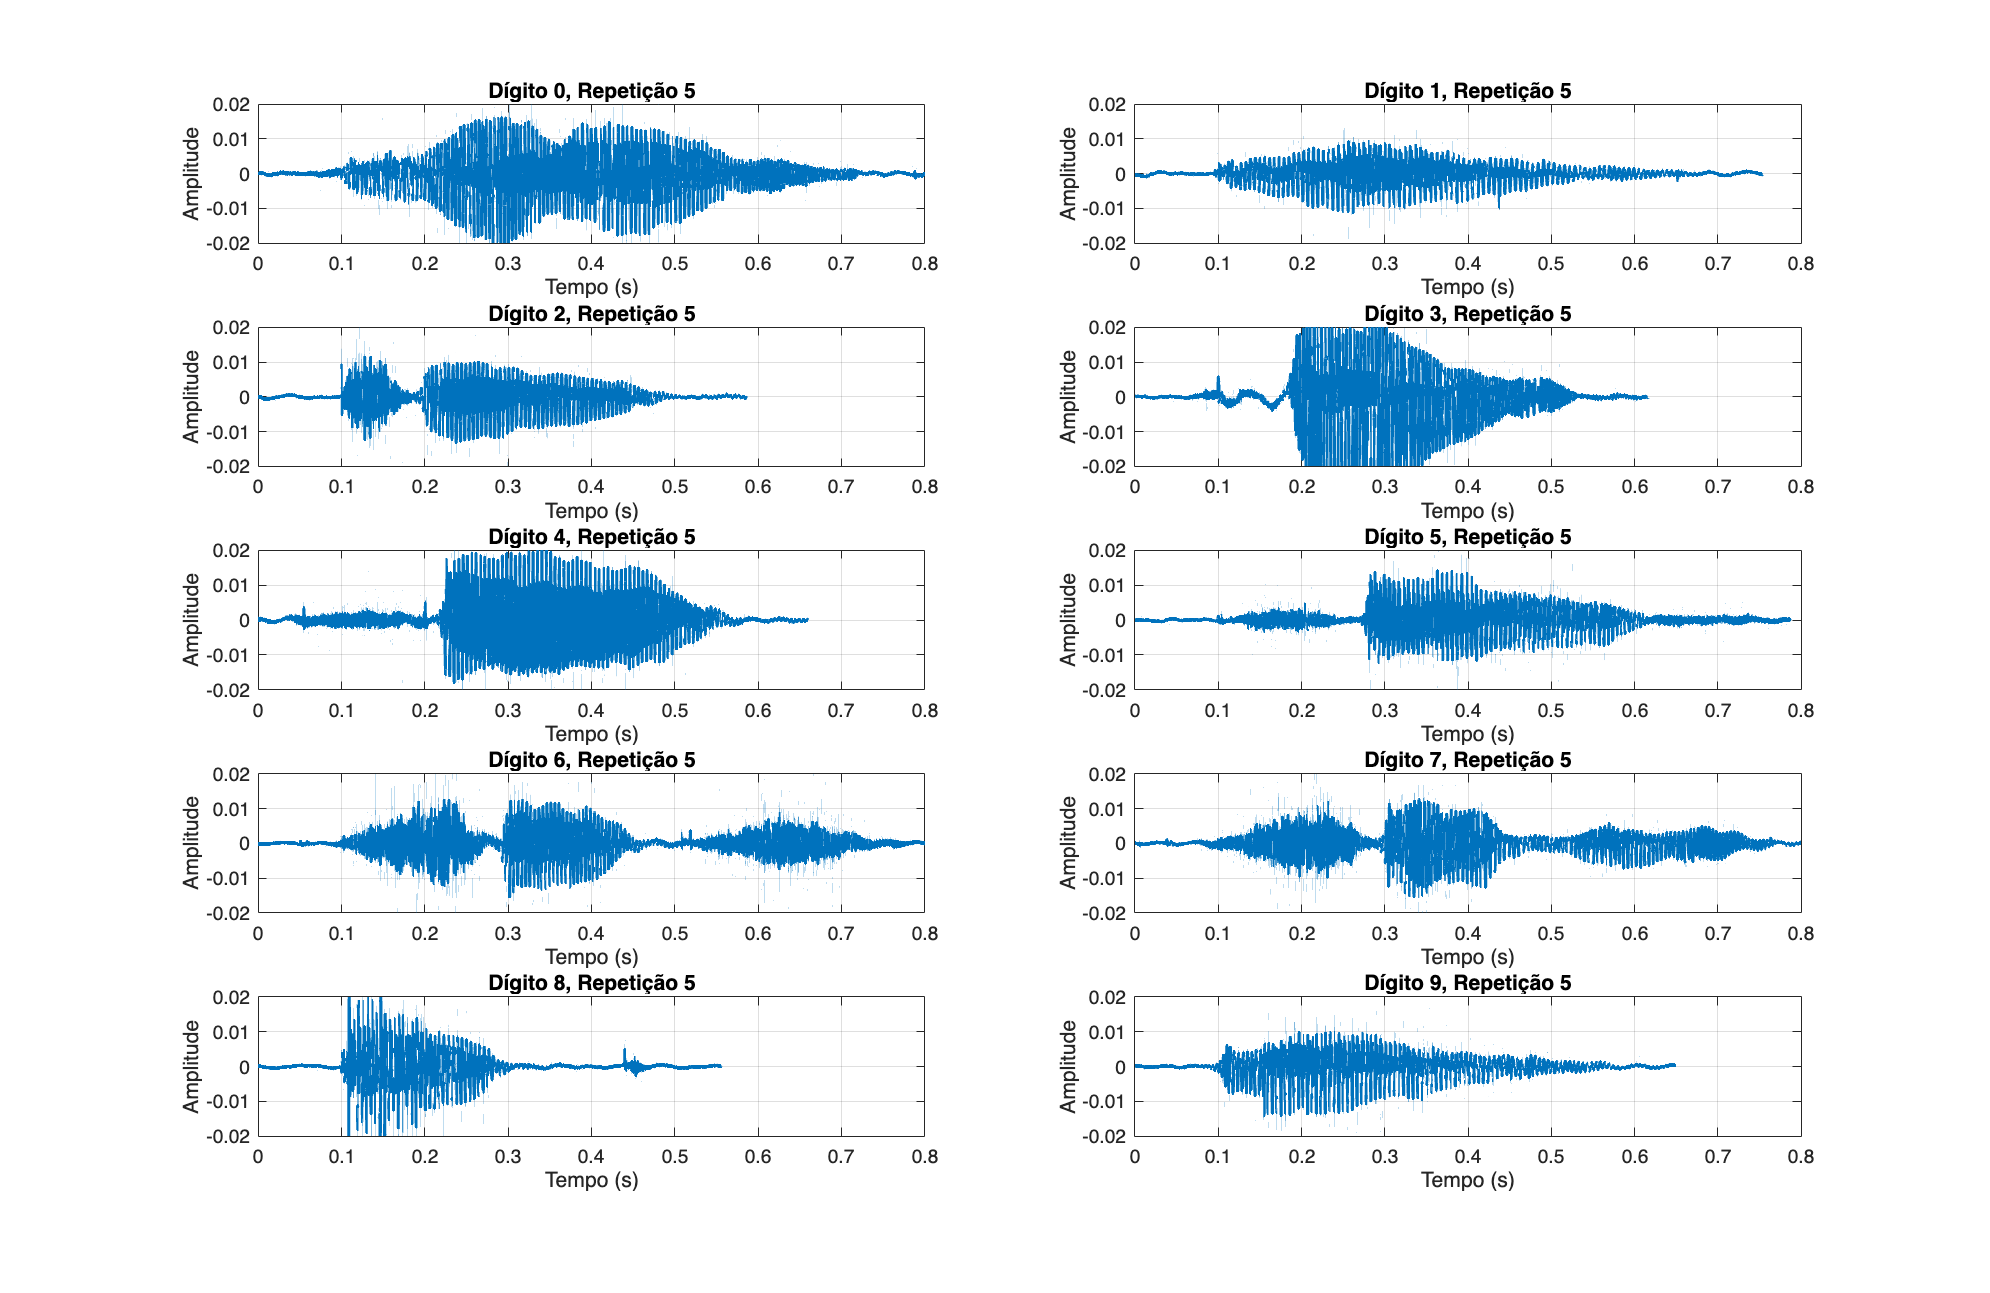

% Extração dos dígitos e repetições
nFiles = height(tabArquivos);
digitos = zeros(nFiles,1);
repeticoes = zeros(nFiles,1);
for i = 1:nFiles
   [~, nomeSemExt, ~] = fileparts(tabArquivos.Nome_Arquivo{i});
   partes = split(nomeSemExt, '_');
   % Primeiro número = dígito
   digitos(i) = str2double(partes{1});
   % Terceiro número = repetição
   repeticoes(i) = str2double(partes{3});
end
tabArquivos.Digito = digitos;
tabArquivos.Repeticao = repeticoes;

% Filtrar apenas a repetição 5
repEscolhida = 5;
T_filtro = tabArquivos(tabArquivos.Repeticao == repEscolhida, :);

% Obter os dígitos disponíveis nessa repetição
uniqueDigitos = unique(T_filtro.Digito);
numDigitos = numel(uniqueDigitos);

if numDigitos < 1
    error('Nenhum dígito disponível na repetição %d.', repEscolhida);
end

% Dois gráficos por linha
nCols = 2;
nRows = ceil(numDigitos / nCols);

% Criar figura mais alta
figure('Name', sprintf('Repetição %d', repEscolhida), 'NumberTitle','off', ...
       'Units','normalized', 'OuterPosition',[0 0 1 1]);

% Plot de gráficos
for i = 1:numDigitos
    currentDigit = uniqueDigitos(i);
    
    % Seleciona, para o dígito atual, o primeiro arquivo
    T_current = T_filtro(T_filtro.Digito == currentDigit, :);
    
    sinal = T_current.Sinal{1};
    fs = T_current.Taxa_Amostragem(1);
    
    % Vetor de tempo para o sinal
    t = (0:length(sinal)-1) / fs;
    
    % Criação do subplot
    subplot(nRows, nCols, i)
    plot(t, sinal, 'LineWidth', 2)
    title(sprintf('Dígito %d, Repetição %d', currentDigit, repEscolhida), 'FontSize', 12)
    xlabel('Tempo (s)', 'FontSize', 12)
    ylabel('Amplitude', 'FontSize', 12)
    set(gca, 'FontSize', 12)

    % Ajuste de limites
    xlim([0 0.8])
    ylim([-0.02 0.02])

    grid on
end

## 4

arquivos = dir(fullfile(path, "*.wav"));
nomes = {arquivos.name}';
taxasAmostragem = zeros(length(arquivos), 1);
sinais = cell(length(arquivos), 1);

for i = 1:length(arquivos)
    caminhoArquivo = fullfile(arquivos(i).folder, arquivos(i).name);
    [sinal, fs] = audioread(caminhoArquivo);
    
    % Remover silêncio inicial
    threshold = 0.02;
    idx = find(abs(sinal) > threshold, 1, 'first');
    if ~isempty(idx)
        sinal = sinal(idx:end);
    end
    
    % Normalizar amplitude para [-1, 1]
    if max(sinal) ~= min(sinal)
        sinal = 2 * (sinal - min(sinal)) / (max(sinal) - min(sinal)) - 1;
    end
    
    % Ajustar duração para 0.8 segundos
    duracao_alvo = 0.8;
    num_amostras_alvo = round(duracao_alvo * fs);
    if length(sinal) < num_amostras_alvo
        sinal = [sinal; zeros(num_amostras_alvo - length(sinal), 1)];
    elseif length(sinal) > num_amostras_alvo
        sinal = sinal(1:num_amostras_alvo);
    end
    
    taxasAmostragem(i) = fs;
    sinais{i} = sinal;
end

tabArquivos = table(nomes, taxasAmostragem, sinais, ...
    'VariableNames', {'Nome_Arquivo', 'Taxa_Amostragem', 'Sinal'})

tabArquivos = 500×3 table
     Nome_Arquivo      Taxa_Amostragem         Sinal      
    _______________    _______________    ________________

    {'0_36_0.wav' }         48000         {38400×1 double}
    {'0_36_1.wav' }         48000         {38400×1 double}
    {'0_36_10.wav'}         48000         {38400×1 double}
    {'0_36_11.wav'}         48000         {38400×1 double}
    {'0_36_12.wav'}         48000         {38400×1 double}
    {'0_36_13.wav'}         48000         {38400×1 double}
    {'0_36_14.wav'}         48000         {38400×1 double}
    {'0_36_15.wav'}         48000         {38400×1 double}
    {'0_36_16.wav'}         48000         {38400×1 double}
    {'0_36_17.wav'}         48000         {38400×1 double}
    {'0_36_18.wav'}         48000         {38400×1 double}
    {'0_36_19.wav'}         48000         {38400×1 double}
    {'0_36_2.wav' }         48000         {38

## 5

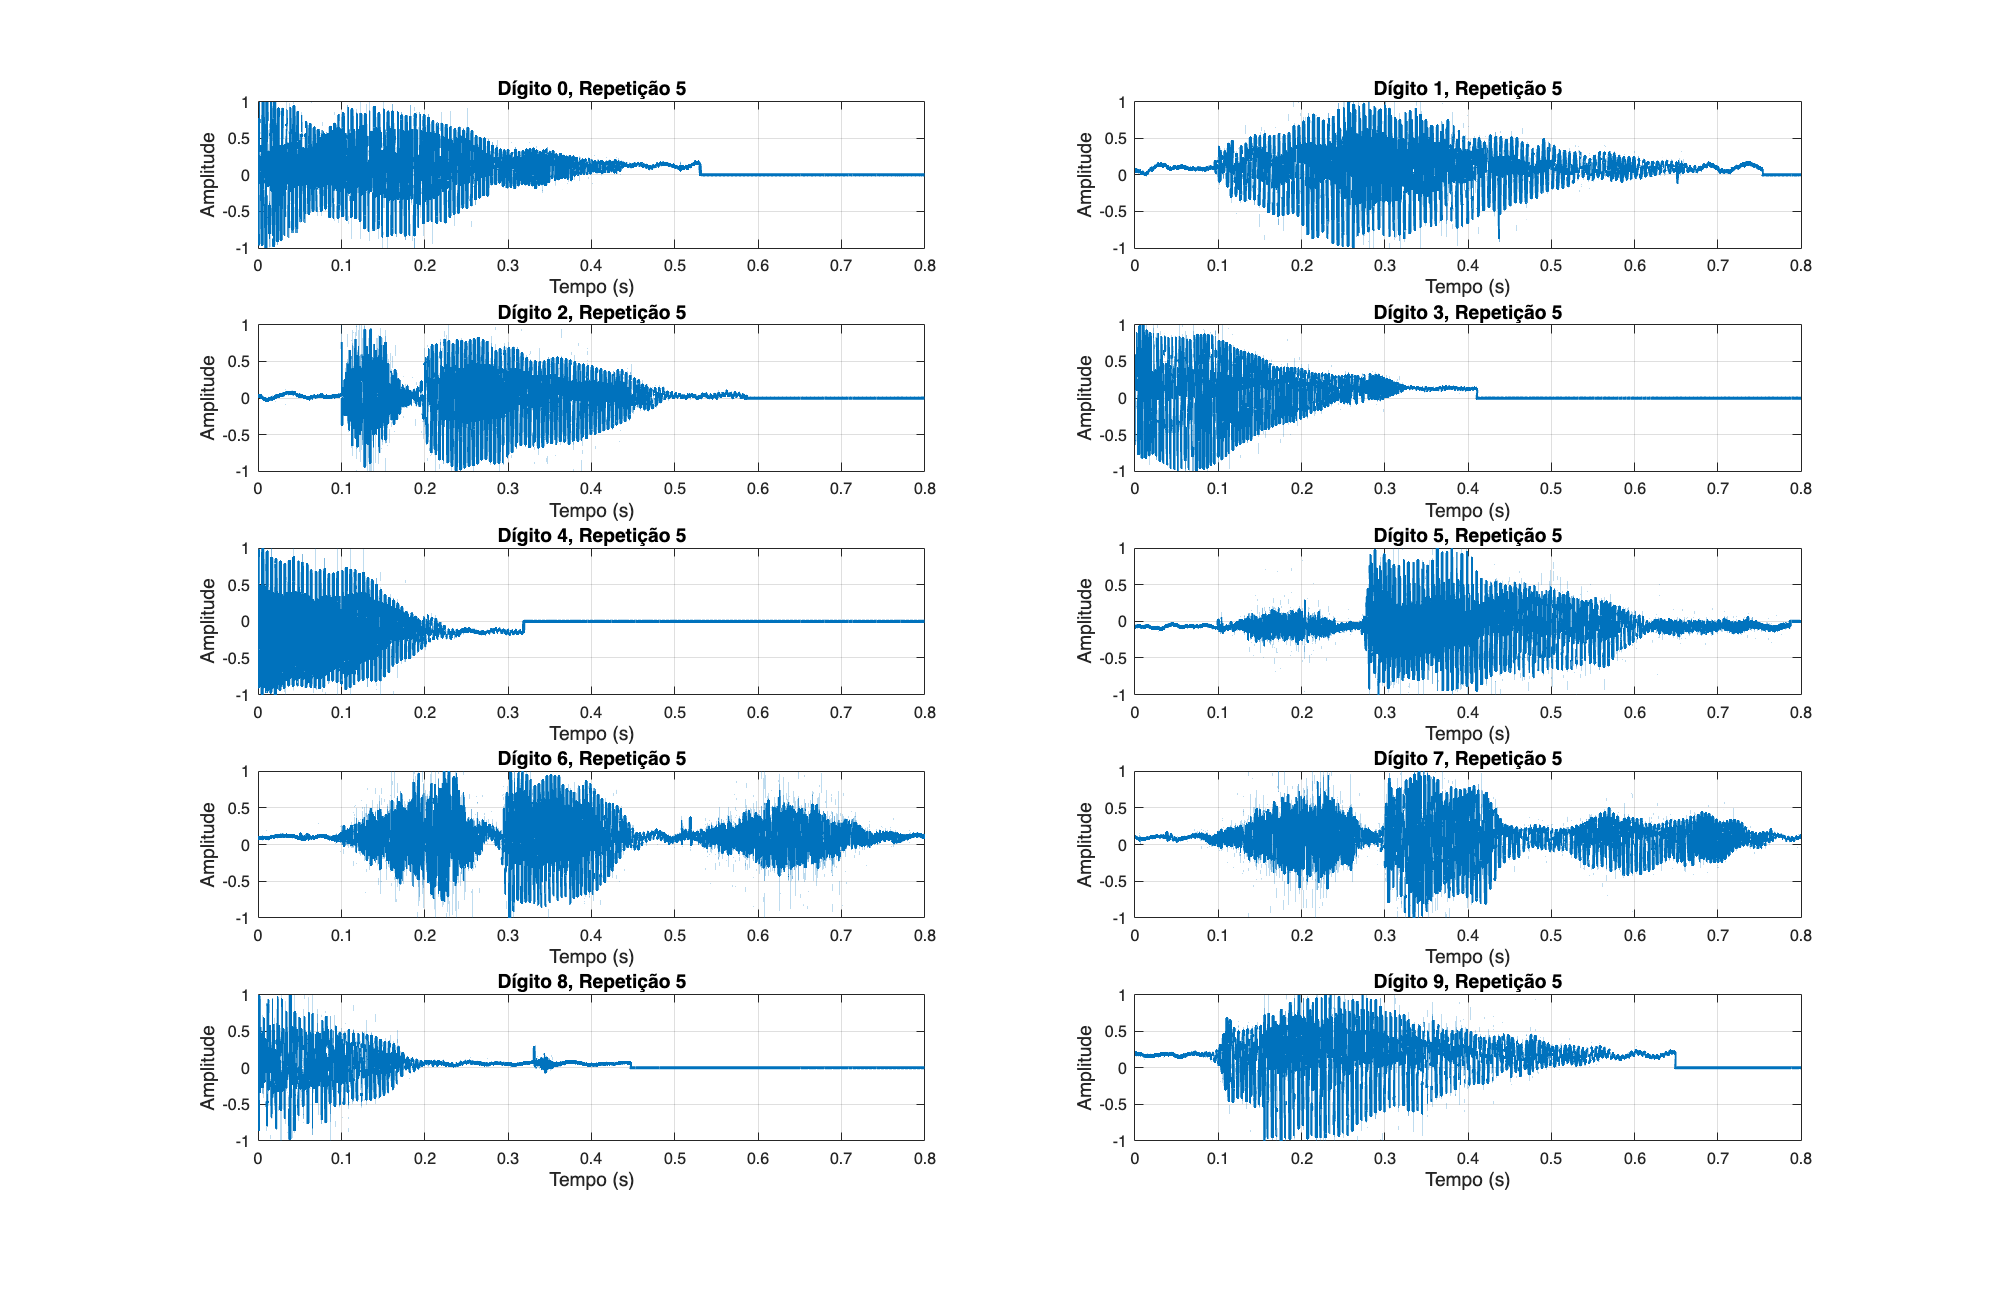

% Extrair dígito e repetição dos nomes dos arquivos
nFiles = height(tabArquivos);
digitos = zeros(nFiles,1);
repeticoes = zeros(nFiles,1);

for i = 1:nFiles
    [~, nomeSemExt, ~] = fileparts(tabArquivos.Nome_Arquivo{i});
    partes = split(nomeSemExt, '_');
    if numel(partes) >= 3
        digitos(i) = str2double(partes{1});
        repeticoes(i) = str2double(partes{3});
    else
        warning('Formato inesperado: %s', tabArquivos.Nome_Arquivo{i});
        digitos(i) = NaN;
        repeticoes(i) = NaN;
    end
end

tabArquivos.Digito = digitos;
tabArquivos.Repeticao = repeticoes;

% Filtrar arquivos da repetição desejada
repEscolhida = 5;
T_filtro = tabArquivos(tabArquivos.Repeticao == repEscolhida, :);
if isempty(T_filtro)
    error('Nenhum arquivo encontrado para a repetição %d.', repEscolhida);
end

% Plotar os sinais para cada dígito
uniqueDigitos = unique(T_filtro.Digito);
numDigitos = numel(uniqueDigitos);
nCols = 2;
nRows = ceil(numDigitos / nCols);

figure('Name', sprintf('Sinais - Repetição %d', repEscolhida), 'NumberTitle','off', ...
       'Units','normalized', 'OuterPosition',[0 0 1 1]);

for i = 1:numDigitos
    currentDigit = uniqueDigitos(i);
    T_current = T_filtro(T_filtro.Digito == currentDigit, :);
    
    sinal = T_current.Sinal{1};
    fs = T_current.Taxa_Amostragem(1);
    t = (0:length(sinal)-1) / fs;
    
    subplot(nRows, nCols, i)
    plot(t, sinal, 'LineWidth', 2)
    title(sprintf('Dígito %d, Repetição %d', currentDigit, repEscolhida), 'FontSize', 12)
    xlabel('Tempo (s)', 'FontSize', 12)
    ylabel('Amplitude', 'FontSize', 12)
    grid on;
end

## 6

% fazer depois

## 7

% Extração de metadados dos nomes dos arquivos
nFiles = height(tabArquivos);
Participante = zeros(nFiles,1);
Digito = zeros(nFiles,1);
Repeticao = zeros(nFiles,1);

for i = 1:nFiles
    [~, nomeSemExt, ~] = fileparts(tabArquivos.Nome_Arquivo{i});
    partes = split(nomeSemExt, '_');
    if numel(partes) >= 3
        Digito(i)       = str2double(partes{1});
        Participante(i) = str2double(partes{2});
        Repeticao(i)    = str2double(partes{3});
    else
        warning('Formato inesperado: %s', tabArquivos.Nome_Arquivo{i});
        Digito(i) = NaN;
        Participante(i) = NaN;
        Repeticao(i) = NaN;
    end
end

tabArquivos.Participante = Participante;
tabArquivos.Digito       = Digito;
tabArquivos.Repeticao    = Repeticao;

% Cálculo das características temporais
EnergiaTotal = zeros(nFiles,1);
EnergiaPrimeiraMetade = zeros(nFiles,1);
EnergiaSegundaMetade  = zeros(nFiles,1);
AmplitudeMaxima       = zeros(nFiles,1);
DesvioPadraoAmplitude = zeros(nFiles,1);

for i = 1:nFiles
    s = tabArquivos.Sinal{i};
    EnergiaTotal(i) = sum(s.^2);
    halfPoint = floor(length(s)/2);
    EnergiaPrimeiraMetade(i) = sum(s(1:halfPoint).^2);
    EnergiaSegundaMetade(i)  = sum(s(halfPoint+1:end).^2);
    AmplitudeMaxima(i)       = max(s);
    DesvioPadraoAmplitude(i) = std(s);
end

% Criação da tabela final com nomes em português (sem diretório de áudio)
finalTable = table(tabArquivos.Nome_Arquivo, tabArquivos.Participante, tabArquivos.Digito, tabArquivos.Repeticao, ...
                   EnergiaTotal, EnergiaPrimeiraMetade, EnergiaSegundaMetade, AmplitudeMaxima, DesvioPadraoAmplitude, ...
    'VariableNames', {'Nome_Arquivo','Participante','Digito','Repeticao','EnergiaTotal','EnergiaPrimeiraMetade','EnergiaSegundaMetade','AmplitudeMaxima','DesvioPadraoAmplitude'});

disp(finalTable)

     Nome_Arquivo      Participante    Digito    Repeticao    EnergiaTotal    EnergiaPrimeiraMetade    EnergiaSegundaMetade    AmplitudeMaxima    DesvioPadraoAmplitude
    _______________    ____________    ______    _________    ____________    _____________________    ____________________    _______________    _____________________

    {'0_36_0.wav' }         36           0           0           2242.1              1539.1                   702.98                  1                   0.2291       
    {'0_36_1.wav' }         36           0           1           3016.8              2817.8                   198.98                  1                  0.26015       
    {'0_36_10.wav'}  

## 8

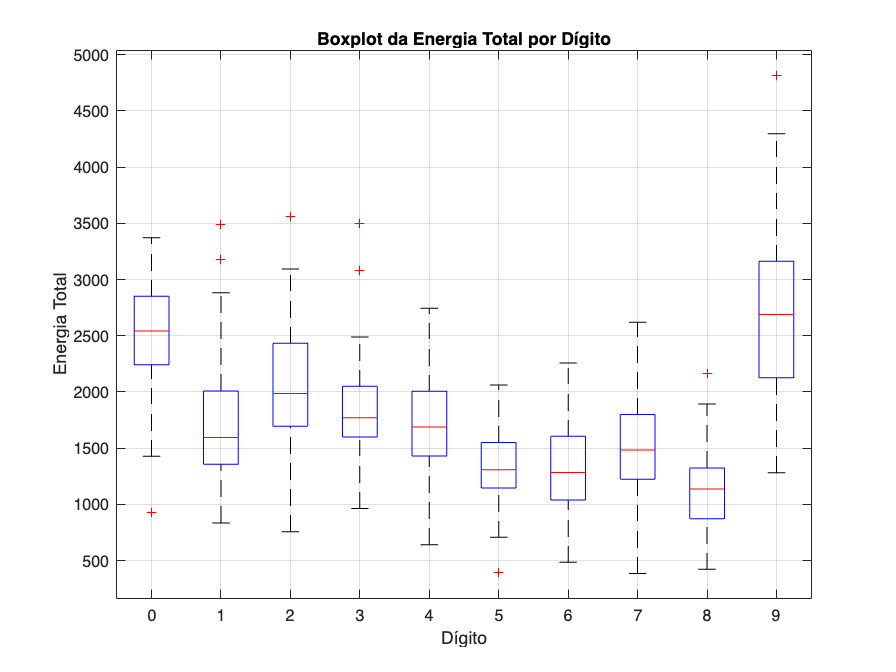

% Cria um boxplot da Energia Total para cada dígito
figure('Name','Boxplot - Energia Total por Dígito','NumberTitle','off');
boxplot(finalTable.EnergiaTotal, finalTable.Digito);
xlabel('Dígito');
ylabel('Energia Total');
title('Boxplot da Energia Total por Dígito');
grid on

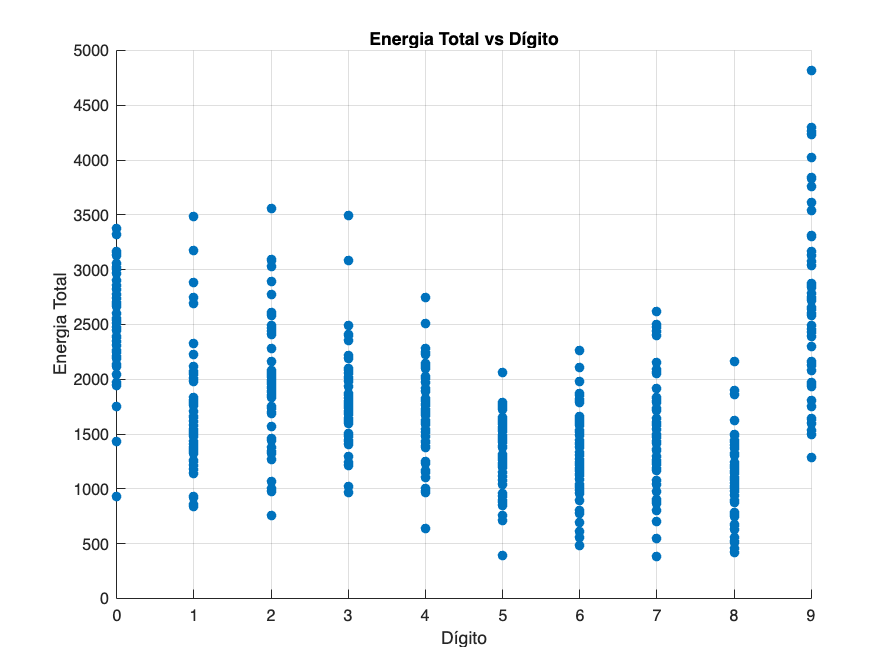


% Cria um scatter plot 2D da Energia Total em função do Dígito
figure('Name','Scatter 2D - Energia Total vs Dígito','NumberTitle','off');
scatter(finalTable.Digito, finalTable.EnergiaTotal, 'filled');
xlabel('Dígito');
ylabel('Energia Total');
title('Energia Total vs Dígito');
grid on

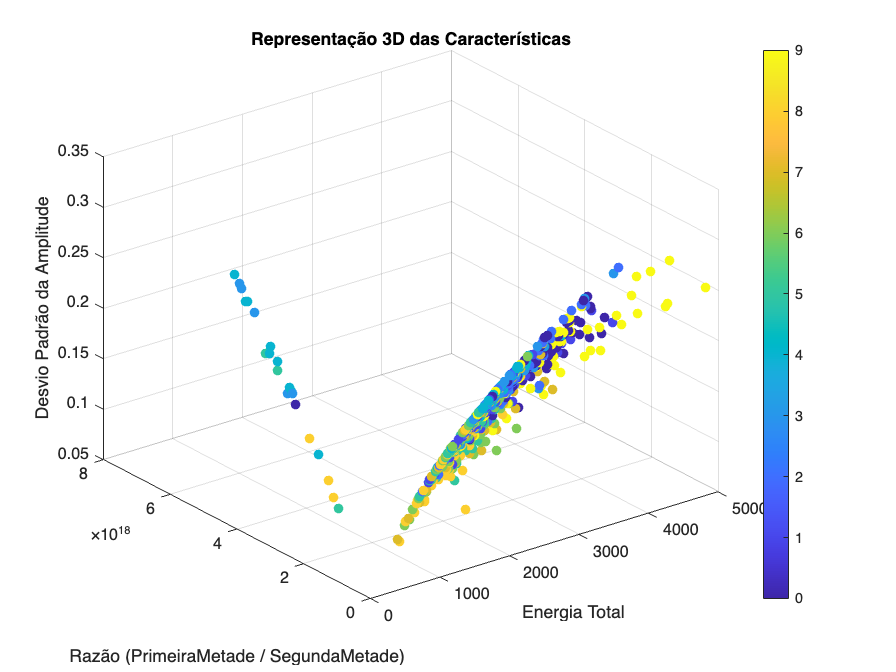


% Calcula a razão entre a energia da primeira metade e a segunda metade
ratioEnergy = finalTable.EnergiaPrimeiraMetade ./ (finalTable.EnergiaSegundaMetade + eps);

% Cria um scatter plot 3D usando Energia Total, a razão calculada e o Desvio Padrão da Amplitude
figure('Name','Scatter 3D - Três Características','NumberTitle','off');
scatter3(finalTable.EnergiaTotal, ratioEnergy, finalTable.DesvioPadraoAmplitude, ...
    36, finalTable.Digito, 'filled');
xlabel('Energia Total');
ylabel('Razão (PrimeiraMetade / SegundaMetade)');
zlabel('Desvio Padrão da Amplitude');
title('Representação 3D das Características');
grid on;
colorbar;